# Get Started with Problem-Based Optimize Live Editor Task

This example script helps you to use the problem-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints:

Minimize ${\rm rosenbrock}(x,y,a)=\log\left (1+a(y - x^2)^2 + (1-x)^2\right)$ subject to the constraint $x^2+y^2\le 1$, where $a=100$ and the initial point $x0$ has $x=-2,\ y=2$. Also, impose the bounds $-3\le x\le 3$, $-2\le y\le 9$.

The code for the objective function appears at the end of this script.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point components `x0x` and `x0y` and scale `a` for the optimization.

x0x = 3;
x0y = 2;
a = 3;

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

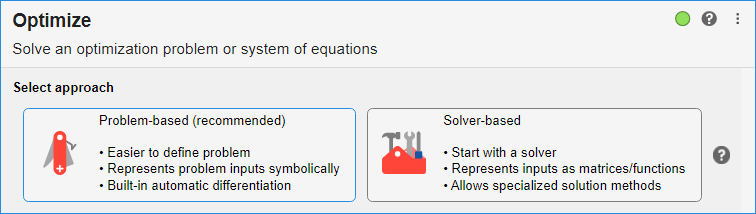

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
zz2 = optimvar("zz","Type","integer","LowerBound",3,"UpperBound",300);

% Set initial starting point for the solver
initialPoint.zz = repmat(3,size(zz2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@NeuralCostFunction,zz2,initialPoint);


% Set nondefault solver options
options = optimoptions("ga","Display","iter","MaxGenerations",7,...
    "PopulationSize",10,"PlotFcn",["gaplotscores","gaplotbestf"]);

% Display problem information
show(problem);

% Solve problem
[solution2,objectiveValue] = solve(problem,initialPoint,"Solver","ga",...
    "Options",options);

% Display results
solution2
objectiveValue

% Clear variables
clearvars zz2 initialPoint options objectiveValue

## Interpret Results

The task calls `solve`, which calls `fmincon` to solve the problem. The top of the task shows that the solution is returned in the `solution` structure. The reported solution, `x = 0.7864` and `y = 0.6177`, satisfies the constraint $x^2+y^2\le 1$, as you can see in the following calculation.

The solver reports exit condition `OptimalSolution` when it stops. To interpret this condition, look at the `exitflag` [output of `solve`](docid:optim_ug.mw_cedf587e-dc58-476c-a675-a44b82bff7c5) for the `fmincon` solver. The description states "First-order optimality measure is less than options.OptimalityTolerance, and maximum constraint violation is less than options.ConstraintTolerance." In other words, the solution is a feasible local minimum.

The objective function value at the solution is 0.0457. This is the smallest objective function value among feasible points.

## Helper Functions

This code creates the `rosenbrock` helper function.

function objective = NeuralCostFunction(zz,~)



opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:E36";

% Specify column names and types
opts.VariableNames = ["ContactTime", "pH", "InitialDyeConcentrationmgLOrPpm", "AdsorbentDosagemg", "TemperatureK"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
ANNdatainput = readtable("C:\Users\Lenovo\Downloads\Matlab_modelling_3124\ANNinputnew.xlsx", opts, "UseExcel", false);
ANNdatainput = table2array(ANNdatainput);
opts = spreadsheetImportOptions("NumVariables", 1);

% Specify sheet and range
opts = spreadsheetImportOptions("NumVariables", 1);

% Specify sheet and range
opts.Sheet = "Adsorption capacity";
opts.DataRange = "A3:A36";

% Specify column names and types
opts.VariableNames = "Adsorption capacity";
opts.VariableTypes = "double";

% Import the data
ANNdataoutput = readtable("C:\Users\Lenovo\Downloads\Matlab_modelling_3124\ANNdataoutput3.xlsx", opts, "UseExcel", false);

ANNdataoutput = table2array(ANNdataoutput);

x=ANNdatainput';
t=ANNdataoutput';




% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.

% Create a Fitting Network
hiddenLayerSize = zz(1);
net = fitnet(hiddenLayerSize,trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,~] = train(net,x,t);

% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = (perform(net,t,y));
%objective=sum(e.^2)/length(e)
objective = sum(e.^2)/length(e);

% View the Network

end

*Copyright 2021-2022 The MathWorks, Inc.*